% Get metadata from H5 file
h5File = "C:\Users\alam\Desktop\EOIRData\VNP46A2.A2021045.h08v06.001.2021104025532.h5";
outputFile = "C:\Users\alam\Desktop\EOIRData\NTLOutput.csv";
h5disp(h5File)

HDF5 VNP46A2.A2021045.h08v06.001.2021104025532.h5 
Group '/' 
    Attributes:
        'RangeBeginningDate':  '2021-02-14'
        'PGE_EndTime':  '2021-02-14 23:59:59.000'
        'WestBoundingCoord':  -100.000000
        'DayNightFlag':  'Day'
        'ShortName':  'VNP46A2'
        'LSIPS_AlgorithmVersion':  'NPP_PR46A2 1.0.3'
        'VerticalTileNumber':  '06'
        'PlatformShortName':  'NPP'
        'identifier_product_doi':  '10.5067/VIIRS/VNP46A2.001'
        'ProcessingEnvironment':  'Linux minion7535 3.10.0-1160.21.1.el7.x86_64 #1 SMP Tue Mar 16 18:28:22 UTC 2021 x86_64 x86_64 x86_64 GNU/Linux'
        'EastBoundingCoord':  -90.000000
        'GRingPointLongitude':  -100.000000 -100.000000 -90.000000 -90.000000 
        'PGENumber':  '555'
        'SatelliteInstrument':  'NPP_OPS'
        'LongName':  'VIIRS/NPP Gap-Filled Lunar BRDF-Adjusted Nighttime Lights Daily L3 Global 500m Linear Lat Lon Grid'
        'DataResolution':  'Moderate'
        'InputPointer':  'VNPLG09GA.

% Get night lights data - make sure that we transpose the data!
NTLdata = h5read(h5File, "/HDFEOS/GRIDS/VNP_Grid_DNB/Data Fields/Gap_Filled_DNB_BRDF-Corrected_NTL")';

% Update fill value to 0 radiance
NTLdata(NTLdata==65535) = 0;

% Apply scale factor, convert nW to W, and then divide by VIIRS DNB
% bandwidth of 0.4 um
NTLdata = double(NTLdata) * 0.1 * 1e-9 / 0.4;

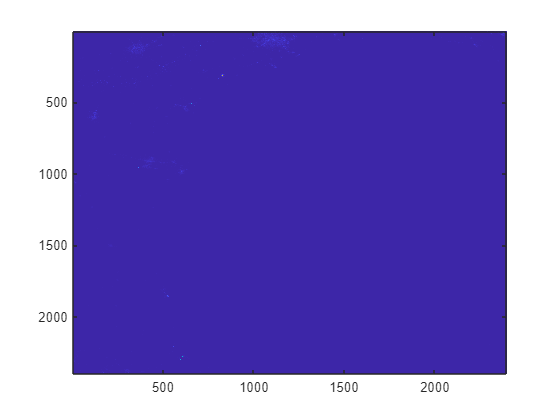

% Write to csv and display data
writematrix(NTLdata, outputFile)
imagesc(NTLdata)